load('AnalogData.mat');
rawData = out.AnalogData

rawData =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


Nround = 21;
Nsample = 2001;

% Manipulate matrix
distanceData = rawData(:, 1)

distanceData =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


analogs = rawData(:, 2)

analogs =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


anaData = reshape(analogs, [Nsample, Nround])'

anaData =            0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0     


% to be used
anaData = cast(anaData, "double");
voltData = anaData .* 3.3 ./ 4096.0 

voltData =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        


meanVoltDataVSRef = -((mean(voltData, 2)/3.3) *100) + 100

meanVoltDataVSRef =   100.0000
  100.0000
   90.9961
   79.9749
   67.5616
   56.1243
   42.0224
   26.4368
   19.5253
   17.5646


measureX = 0 : 5 : 100

measureX =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100


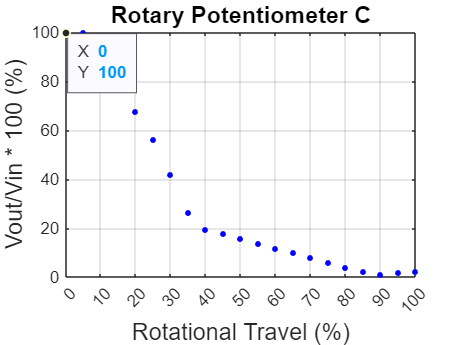

% Plotting
measureGraph = plot(measureX, meanVoltDataVSRef, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
% Add on
datatip(measureGraph);
xticks(0:10:100);
xticklabels(0:10:100);
grid on;

title('Rotary Potentiometer C', 'FontSize', 14);
xlabel('Rotational Travel (%)', 'FontSize', 14); 
ylabel('Vout/Vin * 100 (%)', 'FontSize', 14); 

% Load PlotData
load('rotaryC.mat');
load('x.mat');

% Read and plot datasheet
datasheetValue = rotaryC

datasheetValue =   100.0400   98.2900   86.0600   74.2400   62.8400   50.3200   38.6400   28.1100   22.0900   17.2300   14.7800   12.4900   10.2100    8.0600    5.7700    3.8500    2.2600    1.0200    0.3100    0.3700    0.3700


datasheetX = x;

% Calculate Errors
err = 20/100 * datasheetValue

err =    20.0080   19.6580   17.2120   14.8480   12.5680   10.0640    7.7280    5.6220    4.4180    3.4460    2.9560    2.4980    2.0420    1.6120    1.1540    0.7700    0.4520    0.2040    0.0620    0.0740    0.0740


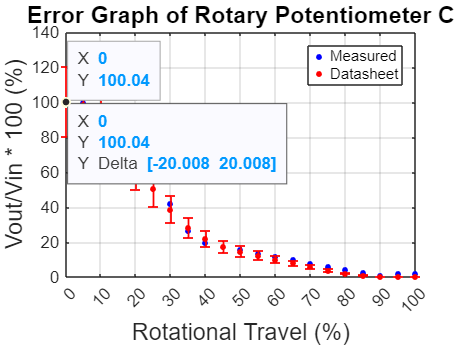

% Plotting Graph
measureGraph;
hold on;
datasheetGraph = plot(datasheetX, datasheetValue, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
errorGraph = errorbar(measureX, datasheetValue, err, 'or', 'LineWidth', 1, 'MarkerSize', 1, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r'); 
hold off;
% Add on
datatip(measureGraph);
datatip(datasheetGraph);
datatip(errorGraph);
xticks(0:10:100);
xticklabels(0:10:100);
grid on;
title('Error Graph of Rotary Potentiometer C', 'FontSize', 14);
xlabel('Rotational Travel (%)', 'FontSize', 14); 
ylabel('Vout/Vin * 100 (%)', 'FontSize', 14);
legend('Measured', 'Datasheet');